## SLE data processing from DSC thermograms

### Setting up script

clear
clc
clf

% Colours for plots
orange = "#D95319";
blue = "#0072BD";
green = "#77AC30";

### User Inputs

% Information about scan
scan_rate = 1                   % K/min

scan_rate = 1


% Analysis variables
sg_filter_raw = 100;            % Savitsky-Golay filter window applied to smooth raw data
sg_filter_derivs = 50;          % Savitsky-Golay filter window applied to smooth derivative data
solidus_window_min = -10;       % Minimum value of window where solidus event occurs
solidus_window_max = 0;         % Maximum value of window where solidus event occurs
liquidus_window_min = 5;        % Minimum value of window where liquidus event occurs
liquidus_window_max = 20;       % Maximum value of window where liquidus event occurs

% offset for x-y solidus point label (graphic purpose only)
offset_x = 0.001;
offset_y = 0.05;

### Data Importing and Pre-Processing

Importing data from .csv file to a table

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Temperature__C_", "HeatFlow_W_g_"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Data01 = readtable("C:\Users\Emlyn\OneDrive - Stellenbosch University\Documents\Masters Work & Research\Thermograms\MATLAB Data Processing\Raw Data\Hermetic Samples\Urea_LevA\HeatRate1K\Urea_LevA_01.csv", opts);

% Clear temporary variables
clear opts

% Display results
Data01

Data01 = 12081×2 table
    Temperature__C_    HeatFlow_W_g_
    _______________    _____________

        -20.997          -0.027881  
        -20.991          -0.027887  
        -20.986          -0.027892  
        -20.981          -0.027898  
        -20.974           -0.02791  
        -20.968          -0.027916  
        -20.963          -0.027923  
        -20.958          -0.027929  
        -20.951          -0.027928  
        -20.944          -0.027936  
        -20.939          -0.027941  
        -20.935          -0.027941  
        -20.928          -0.027949  
        -20.923           -0.02796  
        -20.917          -0.027964  
        -20.911          -0.027957  


Converting data from a table to array for processing

x = table2array(Data01(1:end,"Temperature__C_"));
y = table2array(Data01(1:end,"HeatFlow_W_g_"));


Cleaning up data - using Savitzky-Golay filter 

yy = smoothdata(y,'sgolay',sg_filter_raw);
xx = smoothdata(x,'sgolay',sg_filter_raw);

Fitting the smoothed data using splines

pp = spline(xx,yy);

### Finding the solidus point

Establishing the baseline

threshold = 30-scan_rate*3;
j=1;
for i = 1:length(xx)
    if x(i) >= threshold
        baseline_x(j) = x(i);
        baseline_y(j) = y(i);
        j=j+1;
    end
end

% baseline_x = x(end-350:end);
% baseline_y = y(end-350:end);
coeffs = polyfit(baseline_x,baseline_y,1);          % Linearly fitting the data in this region
m_baseline = coeffs(1);                             % Returning the slope of the fitted line
c_baseline = coeffs(2);                             % Returning the intercept of the fitted line
base_x = linspace(-20,40,200);                      % Generating equation (for plotting purpose only)
base_y = m_baseline*base_x + c_baseline;            % y data

Finding second derivatives

d2pp = fnder(pp,2);                                 % Evaluating second derivatives
d2 = ppval(d2pp,xx);                                % Creating second derivative function with respect to temperature

Finding first derivatives

d1pp = fnder(pp,1);                                 % Evaluating first derivatives
d1 = ppval(d1pp,xx);                                % Creating first derivative function with respect to temperature

Smoothing derivative data - using Savitzky-Golay filter

d2_smooth = smoothdata(d2,'sgolay',sg_filter_derivs);
d1_smooth = smoothdata(d1,'sgolay',sg_filter_derivs);

Plotting the results of smoothed first- and second-derivative

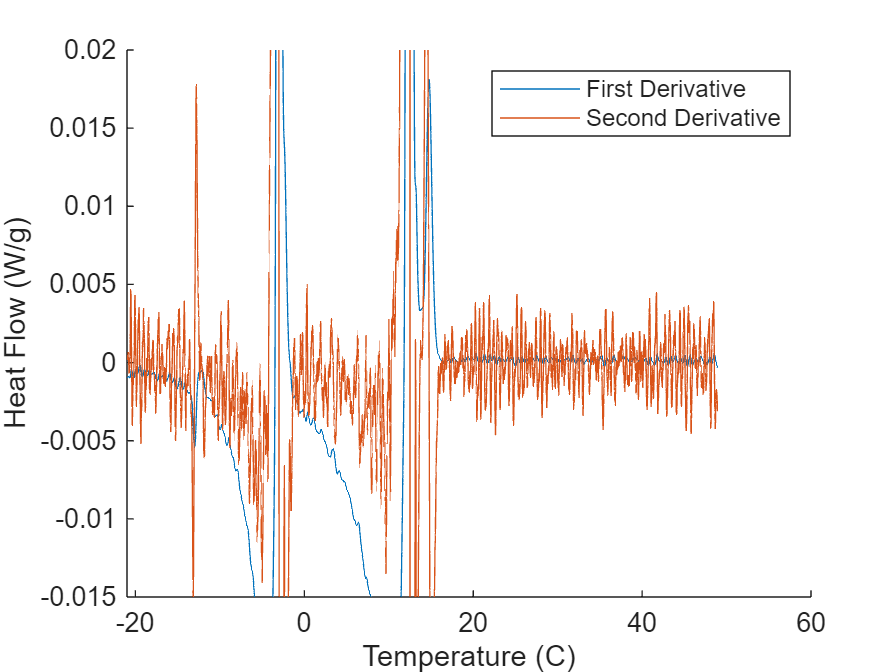

fig1 = figure();
hold on
plot(x,d1_smooth,'Color', blue);
plot(x,d2_smooth,'Color', orange); 
ylim([-0.015,0.02]);
legend('First Derivative','Second Derivative')
xlabel('Temperature (C)')
ylabel('Heat Flow (W/g)')
hold off

Finding the inflection point using second derivative

sol_zero_check = [];

for i = 1:length(d2_smooth)-1                                       % Cycling through the entire array of second derivatives
    if xx(i) > solidus_window_min && xx(i) < solidus_window_max     % Narrowing search window to thermal event of interest
        if d2_smooth(i) < 0 && d2_smooth(i+1) > 0                   % If second derivative of i is less than one and the ith + 1 point is positive, second derivative must cross x=0 axis
        sol_zero_check(i) = d2_smooth(i) .* d2_smooth(i+1);         % Log this as a possible inflection point
        i+1;
        end
    end
end

sol_indices = find(sol_zero_check < 0);                              % Compile all possible infection points

Using first derivative to confirm true inflection point

sol_d1_indices = d1_smooth(sol_indices);                             % First-derivatives at indices corresponding to possible inflection points
sol_d1_value = min(sol_d1_indices);                                  % Local minium of first derivatives
sol_index = find(d1_smooth == sol_d1_value);                         % Return the index of the minimum first derivative

Creating a tangent line equation for the inflection point

sol_x1 = linspace(solidus_window_min,solidus_window_max,100);        % creating array in region of the melting point (for graphic purpose only)
sol_m1 = d1(sol_index);                                              % slope at the inflection point is equal to first derivative at the index of the identified inflection point
sol_c1 = y(sol_index)-sol_m1*x(sol_index);                           % finding the constant of the inflection point tanget
sol_y1 = sol_m1*sol_x1+sol_c1;                                       % Final equation at inflection point

Checking magnitude of gradient is large enough to use time-dependent linear baseline

gradient_check = abs(1/sol_m1)

gradient_check = 39.0426

Finding x-y values intersection of baseline and inflection point tangent

sol_x = (c_baseline-sol_c1)/(sol_m1-m_baseline);                      % x-value of solidus point
sol_y = m_baseline*sol_x + c_baseline;                                % y-value of solidus point

### Finding Liquidus Point

Finding the inflection point using second derivative

liq_zero_check = [];

for i = 1:length(d2_smooth)-1                                       % Cycling through the entire array of second derivatives
    if xx(i) > liquidus_window_min && xx(i) < liquidus_window_max   % Narrowing search window to thermal event of interest
        if d2_smooth(i) > 0 && d2_smooth(i+1) < 0                   % If second derivative of i is less than one and the ith + 1 point is positive, second derivative must cross x=0 axis
        liq_zero_check(i) = d2_smooth(i) .* d2_smooth(i+1);         % Log this as a possible inflection point
        i+1;
        end
    end
end

liq_indices = find(liq_zero_check < 0);                             % Compile all possible infection points

Using first derivative to confirm true inflection point

liq_d1_indices = d1_smooth(liq_indices);                   % First-derivatives at indices corresponding to possible inflection points
liq_d1_value = max(liq_d1_indices);                        % Local minium of first derivatives
liq_index = find(d1_smooth == liq_d1_value);               % Return the index of the minimum first derivative

Finding x-y values intersection of baseline and inflection point tangent

liq_x = x(liq_index);
liq_y = y(liq_index);

#### Plotting results

Identified inflection tangent and baseline with melting point

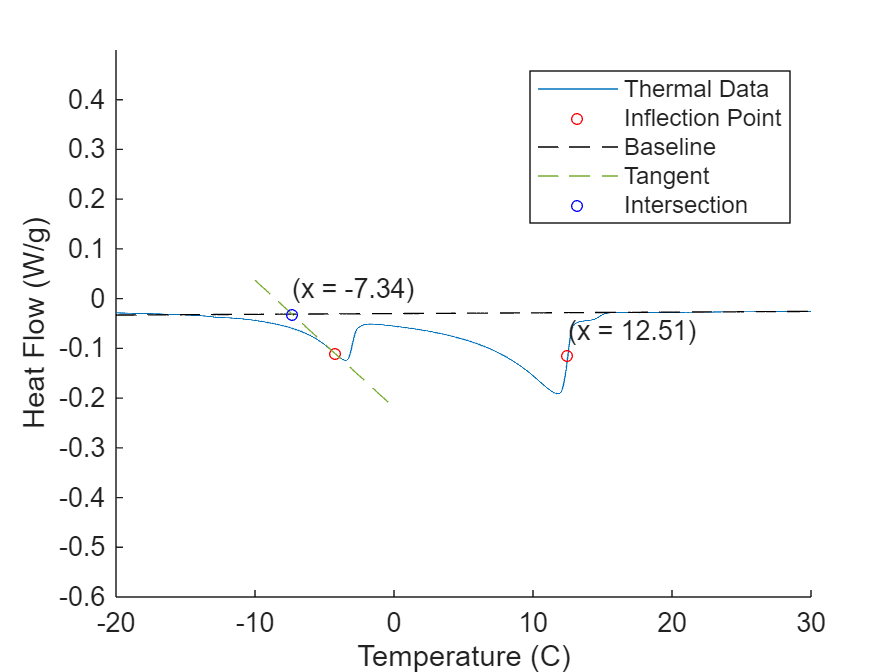

fig2 = figure();
hold on;
plot(x,y,'Color', blue);
plot([x(sol_index), x(liq_index)],[y(sol_index),y(liq_index)],'ro', 'MarkerSize',4);
plot(base_x,base_y,'k--');
plot(sol_x1,sol_y1, '--','Color', green);
plot(sol_x,sol_y,'bo', MarkerSize=4);
legend({'Thermal Data','Inflection Point','Baseline','Tangent','Intersection'},'Location','northeast');
text(sol_x+offset_x,sol_y+offset_y,sprintf('(x = %.2f)', sol_x));
text(liq_x+offset_x,liq_y+offset_y,sprintf('(x = %.2f)', liq_x));
xlabel('Temperature (C)')
ylabel('Heat Flow (W/g)')
ylim([-0.6 0.5])
xlim([-20 30])
hold off;

Identified inflection point on d2 and d1 graphs

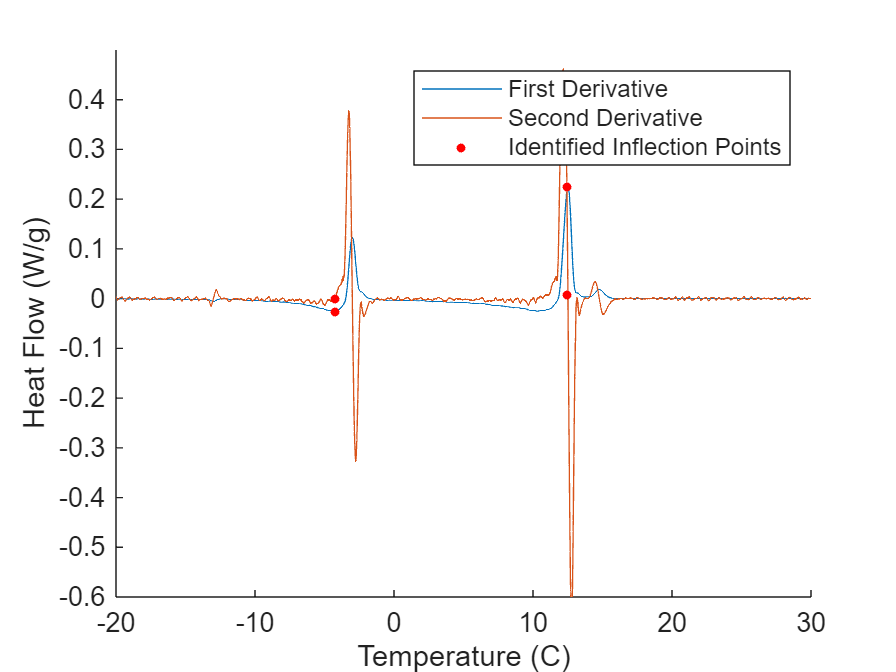

fig3 = figure();
hold on;
plot(x,d1_smooth,'Color', blue);
plot(x,d2_smooth,'Color', orange);
plot([x(sol_index),x(liq_index)],[d1_smooth(sol_index),d1_smooth(liq_index)],'r.','MarkerSize',10);
plot([x(sol_index),x(liq_index)],[d2_smooth(sol_index),d2_smooth(liq_index)],'r.','MarkerSize',10);
legend({'First Derivative','Second Derivative','Identified Inflection Points'},'Location','northeast');
xlabel('Temperature (C)')
ylabel('Heat Flow (W/g)')
ylim([-0.6 0.5])
xlim([-20 30])
hold off;